## Midterm 19/03/2017

### Exercise 1

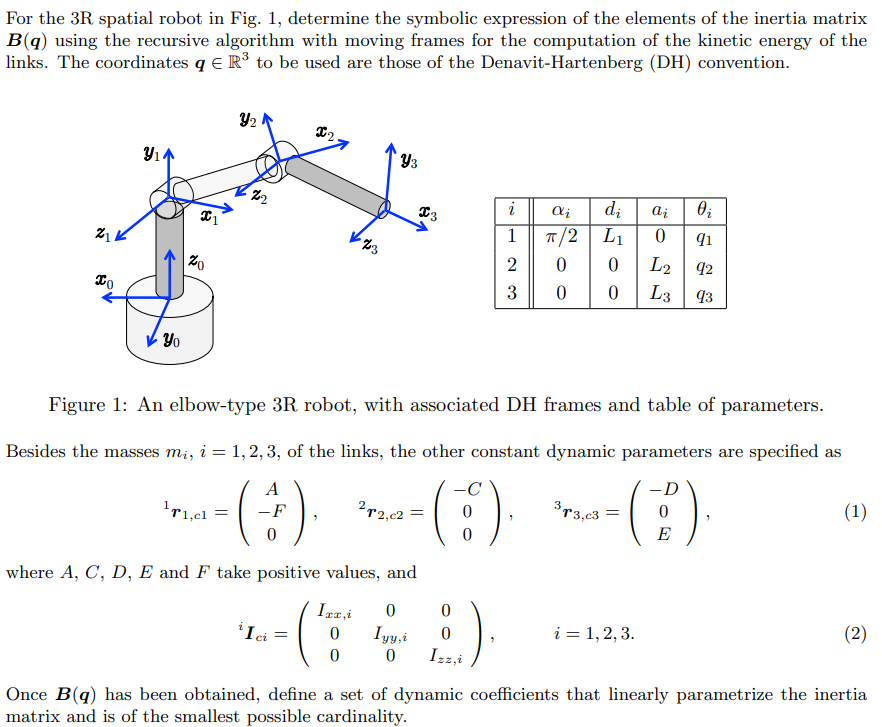

clear all
clc

syms alpha d d1 d2 d4 d6 a a1 a2 a3 a4 theta q1 q2 q3 q4 q5 q6
syms L1 L2 L3

%% number of joints 
N=3;


%% PAY ATTENTION TO THE POSITION OF
%% a and d: a is the second column
%% d the third!

DHTABLE = [  pi/2   L1   0    q1;
             0      0   L2    q2;
             0      0   L3    q3];

         
TDH = [ cos(theta) -sin(theta)*cos(alpha)  sin(theta)*sin(alpha) a*cos(theta);
        sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
          0             sin(alpha)             cos(alpha)            d;
          0               0                      0                   1];

A = cell(1,N);

for i = 1:N 
    alpha = DHTABLE(i,1);
    a = DHTABLE(i,2);
    d = DHTABLE(i,3);
    theta = DHTABLE(i,4);
    A{i} = subs(TDH);
    disp(i)
    disp(A{i})
end

     1



$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & L_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & L_{1}\,\sin\left(q_{1}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

     2



$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 0\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & L_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

     3



$$\left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$



T = eye(4);

for i=1:N 
    T = T*A{i};
    T = simplify(T);
end

T0N = T;

p = T(1:3,4);

n = T(1:3,1);

s = T(1:3,2);

a = T(1:3,3);

A_0_1 = A{1}

$$A\_0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & L_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & L_{1}\,\sin\left(q_{1}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A_0_2 = A{1} * A{2};

A_0_3 = simplify(A{1} * A{2} * A{3},steps=100);

p_01 = A_0_1(1:3, end);
p_02 = A_0_2(1:3, end);
p_03 = A_0_3(1:3, end);

p_0_E = p_03;
p_1_E = p_03 - p_01;
p_2_E = p_03 - p_02;
p_3_E = p_03 - p_03;

R_0_1 = A_0_1(1:3, 1:3);
R_0_2 = A_0_2(1:3, 1:3);
R_0_3 = A_0_3(1:3, 1:3);

z_0 = [0;
       0;
       1];

z_1 = simplify(R_0_1*z_0, Steps=100);
z_2 = simplify(R_0_2*z_0, Steps=100);

p_z_0 = simplify(cross(z_0, p_0_E), steps = 100);
p_z_1 = simplify(cross(z_1, p_1_E), steps = 100);
p_z_2 = simplify(cross(z_2, p_2_E), steps = 100);


%==========================================================
syms dq1 dq2 dq3 real
syms A F C D E positive

% First iteration of Moving Frames algorithm
R_0_1 = A_0_1(1:3, 1:3);
w_0_1 = [0; 0; dq1;];
w_1_1 = R_0_1.'*w_0_1

$$w\_1\_1 = \left(\begin{array}{c} 0\\ {\mathrm{dq}}_{1}\\ 0 \end{array}\right)$$

r_1_1_c1 = [A;-F;0];
v_c1 = cross(w_1_1,r_1_1_c1)

$$v\_c1 = \left(\begin{array}{c} 0\\ 0\\ -A\,{\mathrm{dq}}_{1} \end{array}\right)$$


% Second iteration of Moving Frames algorithm
R_1_2 = simplify(A_0_1(1:3,1:3).'*A_0_2(1:3,1:3), steps=100)

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

w_2_2 = R_1_2.'*(w_1_1+[0;0;dq2;])

$$w\_2\_2 = \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\\ {\mathrm{dq}}_{2} \end{array}\right)$$

w_1_2 = R_1_2*w_2_2

$$w\_1\_2 = \left(\begin{array}{c} 0\\ {\mathrm{dq}}_{1}\,{\cos\left(q_{2}\right)}^{2}+{\mathrm{dq}}_{1}\,{\sin\left(q_{2}\right)}^{2}\\ {\mathrm{dq}}_{2} \end{array}\right)$$

r_1_2 = [0;L2;0;];
v_2_2 = R_1_2.'*(cross(w_1_2,r_1_2))

$$v\_2\_2 = \left(\begin{array}{c} -L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\\ L_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

r_2_2_c2 = [0;0;-C];
v_c2 = v_2_2 + cross(w_2_2,r_2_2_c2)

$$v\_c2 = \left(\begin{array}{c} -C\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)-L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\\ C\,{\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


% Third iteration of Moving Frames algorithm
R_2_3 = simplify(A_0_2(1:3,1:3).'*A_0_3(1:3,1:3), steps=100)

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

w_3_3 = simplify(R_2_3.'*(w_2_2+[0;0;dq3;]), steps=100)

$$w\_3\_3 = \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\sin\left(q_{2}+q_{3}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)\\ {\mathrm{dq}}_{2}+{\mathrm{dq}}_{3} \end{array}\right)$$

w_2_3 = R_2_3*w_3_3

$$w\_2\_3 = \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{3}\right)-{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{3}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{3}\right)+{\mathrm{dq}}_{1}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{3}\right)\\ {\mathrm{dq}}_{2}+{\mathrm{dq}}_{3} \end{array}\right)$$

r_3_3 = [L3;0;0;];
v_3_3 = R_2_3.'*v_2_2+cross(w_3_3,r_3_3)

$$v\_3\_3 = \left(\begin{array}{c} L_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ L_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ -L_{3}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)$$

r_3_3_c3 = [-D;0;E;];
v_c3 = v_3_3 + cross(w_3_3,r_3_3_c3)

$$v\_c3 = \left(\begin{array}{c} \text{E}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)-L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ L_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)-\text{D}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)-\text{E}\,{\mathrm{dq}}_{1}\,\sin\left(q_{2}+q_{3}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+L_{2}\,{\mathrm{dq}}_{2}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \text{D}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)-L_{3}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right) \end{array}\right)$$

***Using the Git Hub's function***

% main.m - Symbolic computation of B(q) for 3R spatial robot using moving frames algorithm

clear; clc;

%% === STEP 1: DEFINE SYMBOLIC PARAMETERS ===
syms q1 q2 q3 dq1 dq2 dq3 real
syms L1 L2 L3 real
syms A C D E F real
syms m1 m2 m3 real

% Inertia tensors
syms Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 real

%% === STEP 2: DEFINE DH MATRIX ===
% Format: [alpha, a, d, theta]
DH = [ pi/2, 0,  L1, q1;
          0, L2, 0,  q2;
          0, L3, 0,  q3];

%% === STEP 3: MASS, VELOCITIES, COM VECTORS, INERTIA MATRICES ===
m = [m1; m2; m3];
qdots = [dq1; dq2; dq3];

% Center of mass vectors (each column is rc_i)
rc = [ A, -C, -D;
      -F,  0,  0;
       0,  0,  E];

% Inertia matrices stacked horizontally
I = [diag([Ixx1, Iyy1, Izz1]), ...
     diag([Ixx2, Iyy2, Izz2]), ...
     diag([Ixx3, Iyy3, Izz3])];

%% === STEP 4: RUN MOVING FRAMES ALGORITHM ===
[w, v, vc, T] = moving_frames_algorithm(3, DH, qdots, m, rc, [], I);

%% === STEP 5: TOTAL KINETIC ENERGY ===
T_total = simplify(T{1} + T{2} + T{3});

%% === STEP 6: COMPUTE INERTIA MATRIX B(q) ===
B = sym(zeros(3));
for i = 1:3
    for j = 1:3
        B(i,j) = simplify( diff(diff(T_total, qdots(i)), qdots(j)) );
    end
end

%% === OUTPUT ===
disp('Total Kinetic Energy:');

Total Kinetic Energy:


disp(T_total);


disp('Inertia Matrix B(q):');

Inertia Matrix B(q):


disp(B);


%% === MOVING FRAMES FUNCTION ===
function [w, v, vc, T] = moving_frames_algorithm(num_joints, DH, qdots, m, rc, prismatic_indices, I)
    % Performs the moving frames algorithm to compute angular and linear
    % velocities, CoM velocities, and kinetic energy terms for a robot.

    % Inputs:
    % num_joints: number of joints
    % DH: Denavit-Hartenberg table [alpha, a, d, theta]
    % qdots: joint velocities
    % m: masses of the links
    % rc: CoM vectors in local frames (each column is rc_i)
    % prismatic_indices: list of prismatic joints (empty for all revolute)
    % I: inertia matrices stacked horizontally [I1, I2, ..., In]

    % Outputs:
    % w: angular velocities
    % v: linear velocities
    % vc: CoM linear velocities
    % T: kinetic energy terms for each link

    v00 = [0; 0; 0];
    w00 = [0; 0; 0];

    % Initialize outputs
    w = sym(zeros(3, num_joints));
    v = sym(zeros(3, num_joints));
    vc = sym(zeros(3, num_joints));
    T = cell(num_joints, 1);

    for i = 1:num_joints
        In = I(1:3, (i-1)*3+1:i*3);

        if ismember(i, prismatic_indices)
            sigma = 1;
        else
            sigma = 0;
        end

        A = DHMatrix(DH(i,:));
        R = A(1:3, 1:3);
        p = A(1:3, 4);
        r_i = R' * p;

        if i == 1
            w_prev = w00;
        else
            w_prev = w(:, i-1);
        end

        wi = R' * (w_prev + (1 - sigma) * [0; 0; qdots(i)]);
        w(:, i) = wi;

        if i == 1
            v_prev = v00;
        else
            v_prev = v(:, i-1);
        end

        vi = R' * (v_prev + sigma * [0; 0; qdots(i)]) + cross(wi, r_i);
        v(:, i) = vi;

        vci = vi + cross(wi, rc(:, i));
        vc(:, i) = vci;

        Ti = simplify(0.5 * m(i) * (vci' * vci) + 0.5 * wi' * In * wi);
        T{i} = Ti;
    end
end

%% === DH TRANSFORMATION FUNCTION ===
function A = DHMatrix(params)
    alpha = params(1);
    a = params(2);
    d = params(3);
    theta = params(4);

    A = [
        cos(theta), -sin(theta), 0, a;
        sin(theta)*cos(alpha), cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
        sin(theta)*sin(alpha), cos(theta)*sin(alpha), cos(alpha), cos(alpha)*d;
        0, 0, 0, 1
    ];
end

### Exercise 3

%% Symbolic setup for a 4R planar robot
syms q1 q2 q3 q4 l

p = [ l*cos(q1)+l*cos(q1+q2)+l*cos(q1+q2+q3)+l*cos(q1+q2+q3+q4);
      l*sin(q1)+l*sin(q1+q2)+l*sin(q1+q2+q3)+l*sin(q1+q2+q3+q4);];
J = jacobian(p,[q1,q2,q3,q4]);

%% Evaluate J at q1=q2=q3=q4=0, l=0.5
J_subs = double(subs(J,[q1,q2,q3,q4,l],[0,0,0,0,0.5]));

v = [0;10];

%% Naive pseudo-inverse solution
J_subs_pinv = pinv(J_subs);
q_dot_unconstrained = J_subs_pinv * v

q_dot_unconstrained =     2.6667
    2.0000
    1.3333
    0.6667



%% Define velocity bounds
% problem statement says: |q̇₁| ≤ 4, |q̇₂| ≤ 2, |q̇₃| ≤ 1, |q̇₄| ≤ 1
constraint_min = [-4; -2; -1; -1];
constraint_max = [ 4;  2;  1;  1];

%% Call the SNS routine
[new_values, old_values] = SNS(v, {J_subs}, constraint_min, constraint_max, 0);

---- SNS for velocity

==========> Loop number: 1
Result: 
    2.6667
    2.0000
    1.3333
    0.6667

Violating min: 0.000000
Violating max: 0.333333
--- Joint 3 exceeded bounds ==> 1.333333
--- Joint 3 now set at 1.000000

==========> Loop number: 2
Result: 
    2.7692
    2.0769
    0.6923

Violating min: 0.000000
Violating max: 0.076923
--- Joint 2 exceeded bounds ==> 2.076923
--- Joint 2 now set at 2.000000

==========> Loop number: 3
Result: 
    2.8235
    0.7059

Violating min: 0.000000
Violating max: -0.000000



disp('==================================')

disp('Old (unconstrained) joint velocities:')

Old (unconstrained) joint velocities:


disp(old_values)

    2.6667
    2.0000
    1.3333
    0.6667



disp('Feasible joint velocities (SNS) satisfying constraints:')

Feasible joint velocities (SNS) satisfying constraints:


disp(new_values)

    2.8235
    2.0000
    1.0000
    0.7059




function [new_values, old_values] = SNS(task, J_array, constraint_min, constraint_max, velocity_initial_condition)
    % This algorithm can handle velocity or acceleration (with dJ).
    %
    %  Inputs:
    %    - task: desired velocity or acceleration
    %    - J_array: {J} (for velocity) or {J,dJ} (for acceleration)
    %    - constraint_min: vector of lower bounds for each joint
    %    - constraint_max: vector of upper bounds for each joint
    %    - velocity_initial_condition: (used only if acceleration)
    %
    %  Outputs:
    %    - new_values: feasible joint velocities/accelerations
    %    - old_values: original unconstrained solution from pinv(J)*task
    
    n_joint = length(constraint_min);
    task    = reshape(task, [], 1);  % ensure column vector
    
    constraint_min = reshape(constraint_min, n_joint, 1);
    constraint_max = reshape(constraint_max, n_joint, 1);
    
    init_value  = -999;
    new_values  = init_value*ones(n_joint,1);

    if length(J_array) == 1
        % Velocity mode
        disp("---- SNS for velocity")
        J         = J_array{1};
        type_task = 'v';
        old_values = pinv(J)*task;
    elseif length(J_array) == 2
        % Acceleration mode
        disp("---- SNS for acceleration")
        J         = J_array{1};
        dJ        = J_array{2};
        type_task = 'a';
        velocity_initial_condition = reshape(velocity_initial_condition, n_joint, 1);
        old_values = pinv(J)*(task - dJ*velocity_initial_condition);
    else
        disp("Error: J_array must be {J} or {J, dJ}")
        return
    end

    for i = 1 : n_joint
        fprintf("\n==========> Loop number: %d\n", i)
        
        % Each iteration, compute the unconstrained solution for the
        % *current* J (which has some columns removed in previous loops).
        if type_task == 'v'
            result = pinv(J)*task;
        else
            % type_task == 'a'
            result = pinv(J)*(task - dJ*velocity_initial_condition);
        end
        
        % result might shrink each iteration, so just ensure column shape:
        result = reshape(result, length(result), 1);
        disp("Result: ")
        disp(result)
        
        % Check for any joint that violates constraints
        violating_max_logical = (result > constraint_max);
        violating_min_logical = (result < constraint_min);
        
        % Max violation distance
        violating_max_value = max( (result - constraint_max) .* violating_max_logical );
        % Min violation distance (will be <= 0 if it actually violates)
        violating_min_value = min( (result - constraint_min) .* violating_min_logical );
        
        fprintf("Violating min: %f\n", violating_min_value)
        fprintf("Violating max: %f\n", violating_max_value)
        
        % If no violations, we can finalize
        if all(~violating_min_logical) && all(~violating_max_logical)
            % Fill in the new_values for any joints not yet assigned
            logic_subs = (new_values == init_value);
            % 'result' belongs only to the reduced set of joints (the ones not saturated yet).
            idx_r = find(logic_subs);
            new_values(idx_r) = result; 
            break
        end
        
        % Pick whichever violation is "largest" in absolute value.
        if abs(violating_min_value) > abs(violating_max_value)
            % Identify which joint index triggered that min violation
            idx_candidates = find( (result - constraint_min) == violating_min_value );
            violating_joint_index = idx_candidates(1); % pick the first
            violation_type = 'violating_min';
        else
            % Identify which joint index triggered that max violation
            idx_candidates = find( (result - constraint_max) == violating_max_value );
            violating_joint_index = idx_candidates(1); % pick the first
            violation_type = 'violating_max';
        end
        
        fprintf("--- Joint %d exceeded bounds ==> %f\n", ...
                violating_joint_index, result(violating_joint_index));
        
        % Saturate that joint to its min or max
        if strcmp(violation_type,'violating_min')
            new_values_index = constraint_min(violating_joint_index);
        else
            new_values_index = constraint_max(violating_joint_index);
        end
        fprintf("--- Joint %d now set at %f\n", violating_joint_index, new_values_index)
        
        % Record the saturated value in new_values
        % But we have to figure out which joint in the "global" sense
        % that this corresponds to.  We can do that by scanning for the
        % next -999 in new_values or by storing an index map. For simplicity
        % here, we’ll just do it with a consistent approach:
        global_indxs = find(new_values == init_value); % unsaturated joints so far
        global_joint = global_indxs(violating_joint_index); 
        new_values(global_joint) = new_values_index;
        
        % Subtract that from the task
        selected_J = J(:,violating_joint_index);
        if type_task == 'v'
            % velocity
            task = task - selected_J * new_values_index;
        else
            % acceleration
            task = task - selected_J * new_values_index;
            dJ(:, violating_joint_index) = [];
            velocity_initial_condition(violating_joint_index) = [];
        end
        
        % Now remove that DOF from J and from constraints
        J(:, violating_joint_index) = [];
        constraint_min(violating_joint_index) = [];
        constraint_max(violating_joint_index) = [];
        
    end % for i=1:n_joint
    
    % If for some reason we used all n_joint loops, the new_values might still
    % have some '-999' entries if not all had to saturate. Fill them with
    % the final partial solution from the last iteration:
    leftover_inds = (new_values == init_value);
    if any(leftover_inds)
        % The last 'result' is for the smaller dimension J
        new_values(leftover_inds) = result; 
    end
    
    new_values = reshape(new_values, n_joint,1);  % final shape
end

### Exercise 4

%% --------- Robot Configuration and Parameters ---------
l = 1;  % link length in meters

% Initial joint configuration
q0 = [pi/2; pi/3; -2*pi/3];

% Desired Cartesian velocity at the end-effector
v = [1; -sqrt(3)];

%% --------- Evaluate Jacobian at q0 ---------
% Jacobian as derived in exercise
J = [-2, -1, -0.5;
      0,  0, sqrt(3)/2];

% From solution: choose columns 1 and 3 for Ja, column 2 for Jb
Ja = J(:, [1 3]);
Jb = J(:, 2);

% Inverse of Ja (from solution)
inv_Ja = [-0.5,   -0.2887;
           0,     1.1547];

%% --------- Gradient of H(q) at q0 ---------
% H(q) = sin^2(q2) + sin^2(q3)
% ∇H(q0) = [0; 2*sin(q2)*cos(q2); 2*sin(q3)*cos(q3)]

% Compute it numerically at q0:
grad_H = [0;
          2 * sin(q0(2)) * cos(q0(2));
          2 * sin(q0(3)) * cos(q0(3))];  % should give [0; 0.8660; 0.8660]

% Reorder q: q = [q1; q2; q3] → q̃ = [q1; q3; q2]
% This is to match q_a = [q1; q3], q_b = q2
grad_H_reordered = grad_H([1 3 2]);

%% --------- Reduced Gradient Computation ---------
% Build transformation G = [ -inv(Ja)*Jb ; 1 ]
G = [-inv_Ja * Jb;
      1];  % shape: 3x1

% Reduced gradient (scalar)
grad_H_reduced = G' * grad_H_reordered;

% Step in reduced gradient space (scalar velocity in direction of q_b)
q_b_dot = grad_H_reduced;

%% --------- Compute q_a_dot from constraints ---------
q_a_dot = inv_Ja * (v - Jb * q_b_dot);

% Reconstruct q_dot = [q1_dot; q3_dot; q2_dot]
q_dot_reordered = [q_a_dot; q_b_dot];

% Undo the reordering: [q1; q3; q2] → [q1; q2; q3]
q_dot = q_dot_reordered([1 3 2]);

%% --------- Display Results ---------
disp('Joint velocities q_dot (Reduced Gradient solution):');

Joint velocities q_dot (Reduced Gradient solution):


disp(q_dot);

   -0.4330
    0.8660
   -2.0000




disp('Verify that J * q_dot ≈ v:');

Verify that J * q_dot ≈ v:


disp(J * q_dot);

    0.9999
   -1.7320




disp('Reduced gradient value:');

Reduced gradient value:


disp(grad_H_reduced);

    0.8660

